# MPC Distrubance Rejection

## System

mcart = 0.493;
mpend = 0.312;
Ipend = 0.00024;
l = 0.04;
f = 0.01;
kt = 0.11;
R = 10;
r = 0.0335;
g = 9.81;
inputGain = 2*kt/(R*r);

% State Space
A = [0 1 0 0;
    0 (-(Ipend + mpend*l^2)*f)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend^2*g*l^2/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0;
    0 0 0 1;
    0 -mpend*l*f/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) mpend*g*l*(mcart+mpend)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2) 0];
B = [0; (Ipend+mpend*l^2)/(Ipend*(mcart+mpend)+ mcart*mpend*l^2);
    0; mpend*l/(Ipend*(mcart+mpend)+ mcart*mpend*l^2)].*1/inputGain;
C= [1 0 0 0];
D = 0;

% Discrete system
sys = ss(A,B,C,D);
sys_d = c2d(sys, 0.005, 'zoh');
fprintf("Rank of ctrb discrete system = %i", rank(ctrb(sys_d)));

Rank of ctrb discrete system = 4


A_d = sys_d.A;
B_d = sys_d.B;
C_d = sys_d.C;

## LQR

lqr_weight = [1e4 1 8e5 1];
Q_lqr = diag(lqr_weight);
R_lqr = 1;

% Discrete controller
K_d = dlqr(A_d, B_d, Q_lqr, R_lqr)

K_d =   -49.8699  -68.0857  461.0194    8.6448


% COntinuous controller
K = lqr(A,B,Q_lqr,R_lqr)

K =  -100.0000 -136.2260  915.2956   14.6294


K = [0 0 6000 100];

## Closed Loop System

% Discrete closed loop
disp("Discrete LQR step")

Discrete LQR step


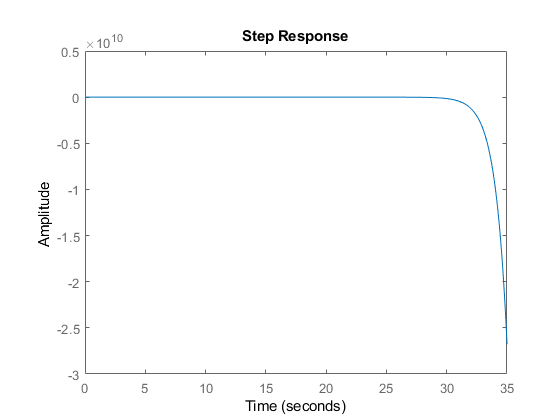

sys_cld = ss(A_d-B_d*K_d, B_d, C_d, D);
step(sys_cld);

eig(A_d-B_d*K_d)

ans =    0.3831 + 0.3222i
   0.3831 - 0.3222i
   0.9963 + 0.0037i
   0.9963 - 0.0037i



disp("Continuous LQR step")

Continuous LQR step


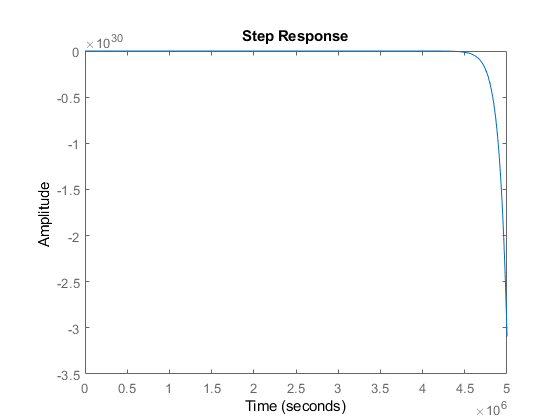

sys_cl = ss(A-B*K, B, C, D);
step(sys_cl);

sys_cl = c2d(sys_cl, 0.005, 'zoh');

A=sys_cl.A;
B=sys_cl.B;
C=sys_cl.C;

## Augmented State Space 

state_n = size(A, 1);
A_new = [A zeros(state_n,1); C 1];
B_new = [B; 0];
C_new = [C 0; zeros(1,state_n) 1];
W_new = [B*K;-1 0 0 0];

input_n = size(B_new, 2);

## MPC Formulation

N = 2;
R = 0.1; % Control penalty
Q = diag([5e4; 0]);  % output = [position; integral of error]
Qbar = blkdiag(Q,Q);
Rbar = blkdiag(R,R);

Tbar = [C_new*A_new;C_new*A_new^2];
Sbar = [C_new*B_new zeros(2,1);C_new*A_new*B_new C_new*B_new];
Wbar = [C_new*W_new;C_new*W_new + C_new*A_new*W_new];
H = (Rbar+Sbar'*Qbar*Sbar);
H = (H+H')/2;

G = [tril(eye(N*input_n));-tril(eye(N*input_n))];
S = zeros(2*N*input_n,5);
W = 12*ones(2*N,1);

iter = 5000;
r = 0.5*ones(iter,1);
%r = 2*square([1:iter+N+1]/200);

Xact = [];
Uopt = [];
X = [0;0;0;0;0];
U = 0;

U_disturb = 0;

warning('off','all')
options = optimoptions('quadprog');
options.Display = 'none';

% Simulation
tic
for ii = 1:iter-1
    Xact(:,ii) = X;

    Rbarref = [r(ii);0;r(ii);0];
    RR = [r(ii) 0 0 0];
    f = 2*(X'*Tbar'*Qbar*Sbar - Rbarref'*Qbar*Sbar - RR*Wbar'*Qbar*Sbar); 
    
    Z = quadprog(H,f,G,W+S*X,[],[],[],[],[],options);
    
    Uopt(ii) = -Z(1) - U_disturb;
    U = Uopt(ii);

    X = A_new*X + B_new*U + W_new*RR';
end
toc

Elapsed time is 8.756296 seconds.


Xact(:,ii+1) = X;

## Plotting

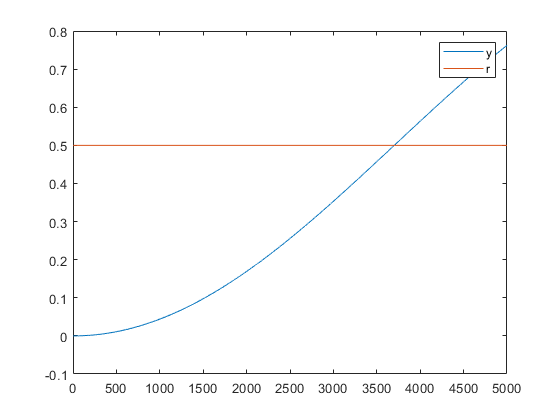

% Plotting
y=C_new*Xact;

plot([1:iter],y(1,1:iter),[1:iter],r(1:iter))
legend('y','r')

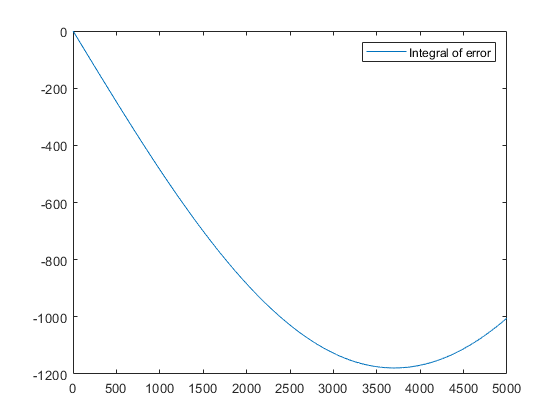

plot([1:iter],y(2,1:iter))
legend('Integral of error')

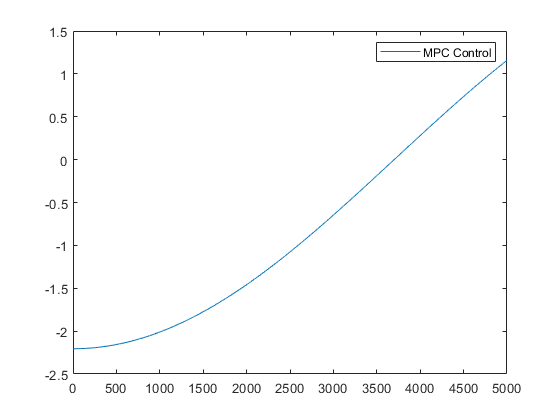

ref_error = [r(1:end-1)'-Xact(1, 1:end-1); -Xact(2:4,1:end-1)];
plot([1:iter-1], Uopt(1, 1:iter-1))
legend('MPC Control')